  %% Load data
    root_folder = 'E:\Project_A\project_share\Project_A_image_full'
    train_folder = 'train'
    class_folder = 'class'
    full_path_train = fullfile(root_folder, train_folder);
    full_path_class = fullfile(root_folder, class_folder);
    imds = imageDatastore(full_path_train, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 

root_folder = 'E:\Project_A\project_share\Project_A_image_full'

train_folder = 'train'

class_folder = 'class'

   %% split train & validation
    [imdsTrain,imdsValidation] = splitEachLabel(imds,0.875);

%% Load pretrained network
net = alexnet;
analyzeNetwork(net)
layersTransfer = net.Layers(1:end-3); % replace final layers, last 3 layers are configured for 1000 classes   
inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


%% Data for classification
    imdsTest = imageDatastore(full_path_class, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
    augimdsTest = augmentedImageDatastore(inputSize,imdsTest,"ColorPreprocessing","gray2rgb");



numClasses = numel(categories(imdsTrain.Labels))

numClasses = 5

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];
pixelRange = [-30 30];


imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain, ...
    'DataAugmentation',imageAugmenter,'ColorPreprocessing','gray2rgb');
augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation,"ColorPreprocessing","gray2rgb");

%% Training options
miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-3, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');
    options.ExecutionEnvironment = 'gpu';
   


## Train network

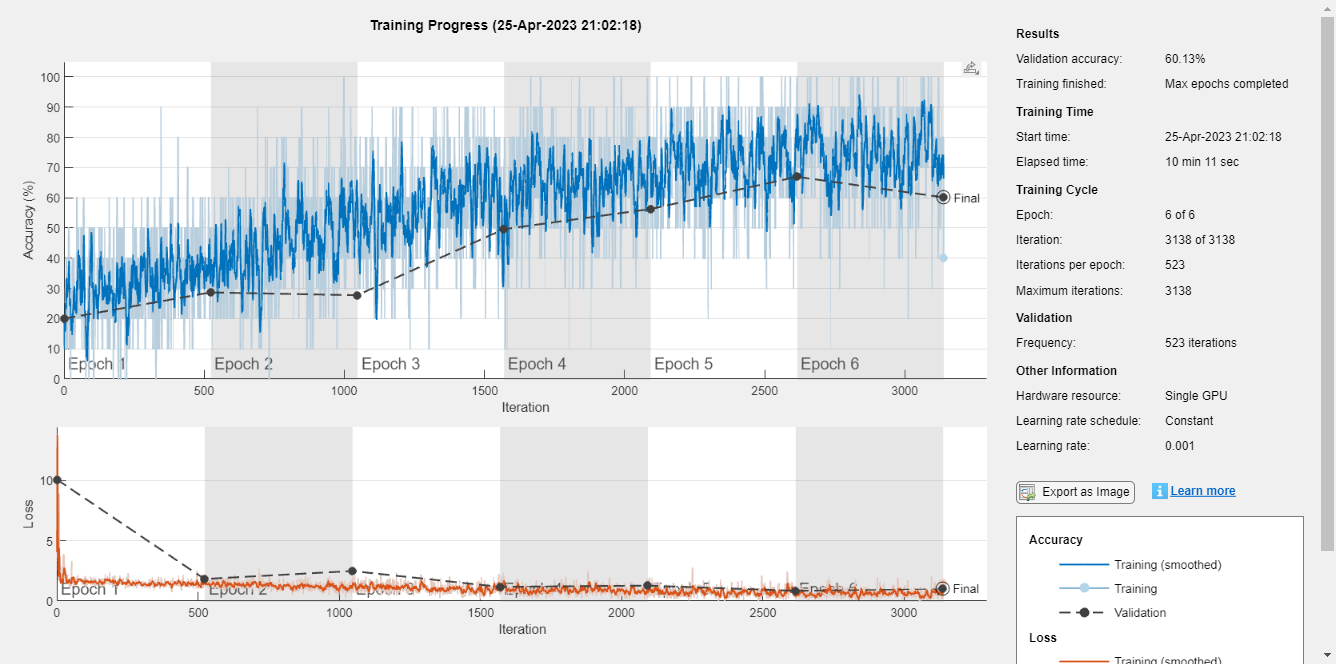

netTransfer = trainNetwork(augimdsTrain,layers,options);

## Classify validation images

[YPred,scores] = classify(netTransfer,augimdsValidation);
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.6013

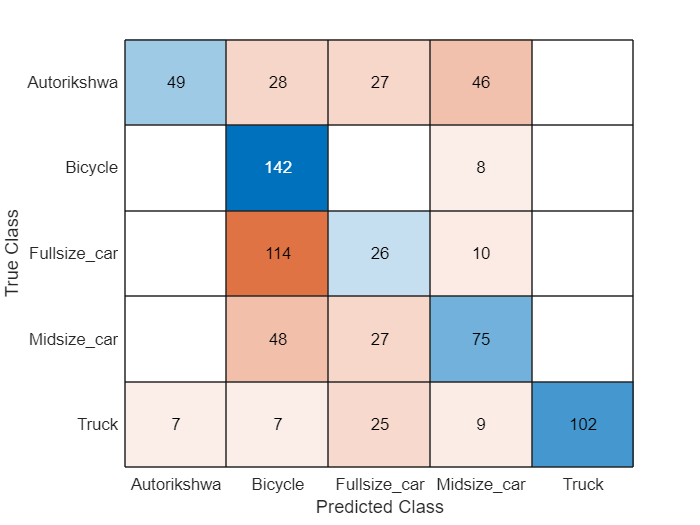

confusionchart(YValidation,YPred)

## Classify test images

[YPred1,scores1] = classify(netTransfer,augimdsTest);
YTest = imdsTest.Labels;
    accuracy_test = mean(YPred1 == YTest)

accuracy_test = 0.6646

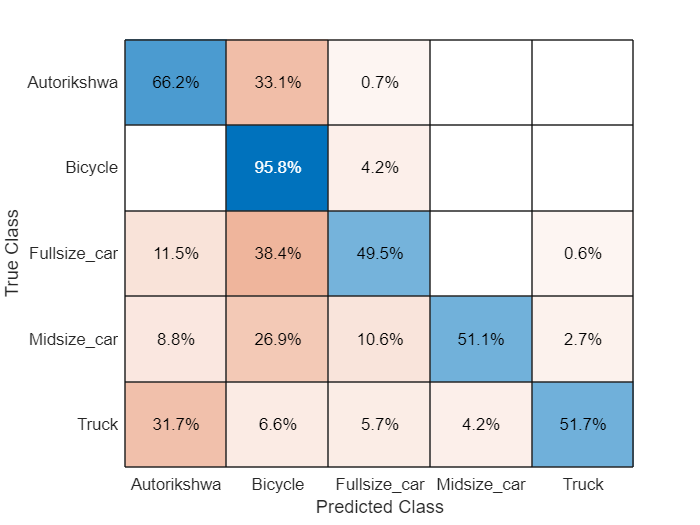

    confusionchart(YTest,YPred1)

## Caculate F1 score

f1 = calculateF1score(YTest,YPred1);